%% 2稿目アンケート回答のグラフ化用スクリプト
%% 回答結果整列
clear, clc, close all
list = dir('*.csv');
numFiles = length(list);
Mx = cell(numFiles,2);% インポート用のセル

% 条件の順番ごとに並び替えて集計
condName = ["None_come";"Vision_come";"Haptic_come";"Vis_Hap_come";
            "None_trans";"Vision_trans";"Haptic_trans";"Vis_Hap_trans";];
qNum = 5; condNum = 8;
ansReOrd = zeros(12,40); % 整列後の回答まとめ
% Q1-NC VC HC VHC NT VT HT VHT | Q2- .... 
for i = 1:numFiles
    Mx{i,1} = readcell(list(i).name);
    for k = 1:3
        subj = cell2mat(Mx{i,1}(k+1,2));
        % 回答を並び替える
        for c = 1:8
            for q = 1:5
                idx = contains(Mx{i,1}(1,:),condName(c,1)) & contains(Mx{i,1}(1,:),"Q"+num2str(q));
                str = cell2mat(Mx{i,1}(k+1,idx));
                for rate = 0:6
                    if contains(str,num2str(rate))
                        ansReOrd(subj,8*(q-1)+c)  = rate;
                    end
                end
                
            end
        end
    end
end

save;

ansMean = mean(ansReOrd)
reshape(ansMean,[8,5])

## 全回答スコア表示

close all
titleTxt = ["Q1 This music evokes the sensation of wanting to move some part of my body."; ...
"Q2 Listening to this music gives me pleasure.";...
"Q3 I can find the target easily."; ...
"Q4 I can find the target intuitively.";...
"Q5 I enjoyed the experience.";];
xLabelText = repmat(["M1";"M2"],5,1);

for i = 1:5
    figure('Position',[0 0 720 250])
    tmp = ansReOrd(:,8*(i-1)+1:8*i);
    data = tmp(:,[1,5,2,6,3,7,4,8]);
    hold on
    xl = repmat(1:size(data,2),size(data,1),1);
    dotSize = .8;
    boxplot(data,'Whisker',99,'Colors','k');
    % beeswarm を使うため、12*40 を 480*1 に変形する
    y = reshape(data,[size(data,1)*size(data,2),1]);
    x = reshape(xl,[size(data,1)*size(data,2),1]);
    cmap = repmat([0 0 1],size(data,2),1);
    beeswarm(x,y,'dot_size', dotSize,'colormap',cmap,...
    'MarkerFaceAlpha',1,'MarkerEdgeColor','none'); 
    % swarmchart(xl,data,[],...
    %     'blue','filled', 'SizeData',15);
    plot(1:size(data,2),mean(data),'+r');
    ylabel('Score');
    ylim([-0.5,6.5]);
    yticks([0 1 2 3 4 5 6]);
    title(titleTxt(i,1));
    xticklabels(xLabelText);
    ax = gca; % current axes
    ax.FontSize = 14;
    ax.FontName = 'tahoma';
    set(gcf, 'visible', 'on')
    saveas(gcf,strcat('score_Q',num2str(i),'.png'));
    box off
    hold off
end





## 1枚に描画（恐らく没）

close all
figure('Position',[0 0 720 340])
data = ansReOrd;
hold on
xl = repmat(1:size(data,2),size(data,1),1);
dotSize = .8;
boxplot(data,'Whisker',99,'Colors','k');
% beeswarm を使うため、12*40 を 480*1 に変形する
y = reshape(data,[size(data,1)*size(data,2),1]);
x = reshape(xl,[size(data,1)*size(data,2),1]);
cmap = repmat([0 0 1],size(data,2),1);
beeswarm(x,y,'dot_size', dotSize,'colormap',cmap,...
'MarkerFaceAlpha',1,'MarkerEdgeColor','none'); 
plot(1:size(data,2),mean(data),'+r');
ylabel('Score');
title('ScoreAll');
xticklabels(condName);
ax = gca; % current axes
ax.FontSize = 12;
ax.FontName = 'tahoma';
set(gcf, 'visible', 'on')
saveas(gcf,strcat('score_all','.png'));
box off
hold off


## 差分データ表示

% None vs Haptic
% Vision vs Haptic
% Haptic vs Vis_Hap
% condName = ["None_come";"Vision_come";"Haptic_come";"Vis_Hap_come";
%             "None_trans";"Vision_trans";"Haptic_trans";"Vis_Hap_trans";];
data = ansReOrd;
diffCell = cell(4,1);
% diff_HN = zeros(12,10);
% diff_HV = zeros(12,10);
% diff_HVH = zeros(12,10);
% diff_CT = zeros(12,20);
for q = 1:5
    % 各条件の列番号
    NC = 1+8*(q-1);
    VC = 2+8*(q-1);
    HC = 3+8*(q-1);
    VHC = 4+8*(q-1);
    NT = 5+8*(q-1);
    VT = 6+8*(q-1);
    HT = 7+8*(q-1);
    VHT = 8+8*(q-1);

    % Haptic -None
    diffCell{1,1}(:,2*(q-1)+1) = data(:,HC)-data(:,NC);
    diffCell{1,1}(:,2*q) = data(:,HT)-data(:,NT);
    % Haptic - Vision
    diffCell{2,1}(:,2*(q-1)+1) = data(:,HC)-data(:,VC);
    diffCell{2,1}(:,2*q) = data(:,HT)-data(:,VT);
    % Vis_Hap - Vision
    diffCell{3,1}(:,2*(q-1)+1) = data(:,VHC)-data(:,VC);
    diffCell{3,1}(:,2*q) = data(:,VHT)-data(:,VC);
    % Vis_Hap - Haptic
    diffCell{4,1}(:,2*(q-1)+1) = data(:,VHC)-data(:,HC);
    diffCell{4,1}(:,2*q) = data(:,VHT)-data(:,HT);
    % Come-Trans
    diffCell{5,1}(:,4*q-3) = data(:,NC)-data(:,NT);
    diffCell{5,1}(:,4*q-2) = data(:,VC)-data(:,VT);
    diffCell{5,1}(:,4*q-1) = data(:,HC)-data(:,HT);
    diffCell{5,1}(:,4*q)   = data(:,VHC)-data(:,VHT);
end

diffDesc = ["Haptic-None";"Haptic-Vision";"VisHap-Vision";"VisHap-Haptic";"Come-Trans"];
% diffCondLabel = ["Q1C";"Q1T";"Q2C";"Q2T";"Q3C";"Q3T";"Q4C";"Q4T";"Q5C";"Q5T"];
diffCondLabel = repmat(["M1";"M2"],5,1);

diffMvLabel = repmat(["None";"Vision";"Haptic";"VisHap"],5,1);

for i = 1:size(diffDesc,1)
    diffCell{i,2} = diffDesc(i,1);
    if i==5
        diffCell{i,3} = diffMvLabel;
    else
        diffCell{i,3} = diffCondLabel;
    end
end

close all
for i = 1:size(diffCell,1)
    figure('Position',[0 0 720 340])
    data = diffCell{i,1};
    hold on
    xl = repmat(1:size(data,2),size(data,1),1);
    dotSize = .8;
    boxplot(data,'Whisker',99,'Colors','k');
    % beeswarm を使うため、12*40 を 480*1 に変形する
    y = reshape(data,[size(data,1)*size(data,2),1]);
    x = reshape(xl,[size(data,1)*size(data,2),1]);
    cmap = repmat([0 0 1],size(data,2),1);
    beeswarm(x,y,'dot_size', dotSize,'colormap',cmap,...
    'MarkerFaceAlpha',1,'MarkerEdgeColor','none'); 
    plot(1:size(data,2),mean(data),'+r');
    ylabel('Score difference');

    title(cell2mat(diffCell{i,2}));
    label = diffCell{i,3};
    xticklabels(label);

    ax = gca; % current axes
    ax.FontSize = 14;
    ax.FontName = 'tahoma';
    set(gcf, 'visible', 'on')
    saveas(gcf,strcat(cell2mat(diffCell{i,2}),'.png'));
    box off
    hold off
end
save;

% ylim([-0.5,6.5]);
% yticks([-1 0 1 2 3 4 5 6]);
% yticks([-3 -2 1 0 1 2 3]);

## 動画用差分(Q1:HN,HV,VHV, Q2:..., Q5)

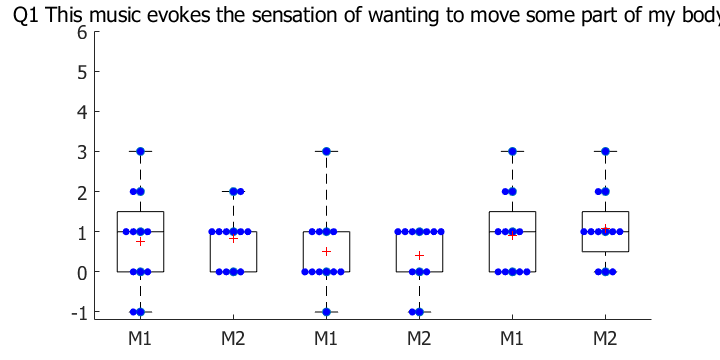

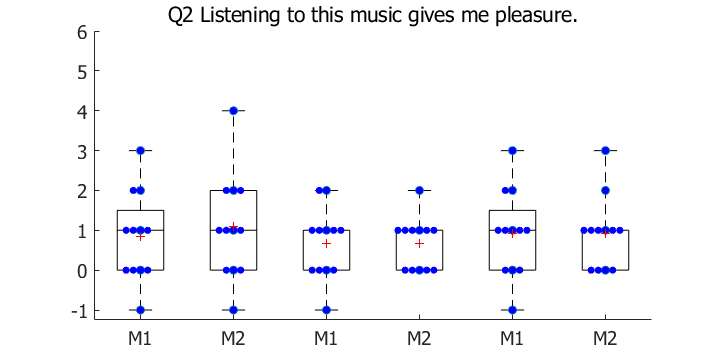

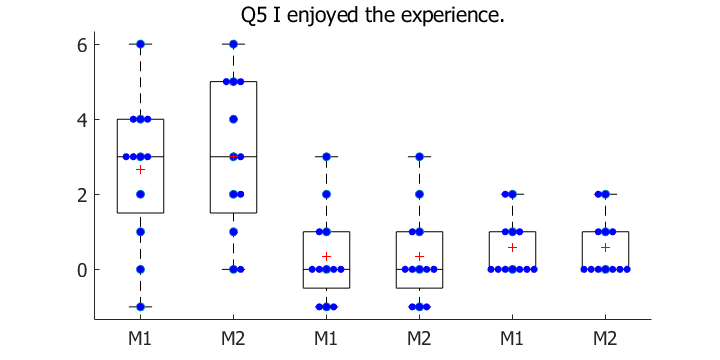

close all
titleTxt = ["Q1 This music evokes the sensation of wanting to move some part of my body."; ...
"Q2 Listening to this music gives me pleasure.";...
"Q5 I enjoyed the experience.";];
data = zeros(12,6);
for i = 1:3
    figure('Position',[0 0 720 360])
    for k=1:3
        if i~=3
            data(:,[2*k-1,2*k]) = diffCell{k,1}(:,[2*i-1,2*i]);
        else
            data(:,[2*k-1,2*k]) = diffCell{k,1}(:,[9,10]);
        end
    end
    ylim([-1,6]);

    hold on
    xl = repmat(1:size(data,2),size(data,1),1);
    dotSize = .8;
    boxplot(data,'Whisker',99,'Colors','k');
    % beeswarm を使うため、12*40 を 480*1 に変形する
    y = reshape(data,[size(data,1)*size(data,2),1]);
    x = reshape(xl,[size(data,1)*size(data,2),1]);
    cmap = repmat([0 0 1],size(data,2),1);
    beeswarm(x,y,'dot_size', dotSize,'colormap',cmap,...
    'MarkerFaceAlpha',1,'MarkerEdgeColor','none'); 
    plot(1:size(data,2),mean(data),'+r');

    title(titleTxt(i,1));
    label = diffCell{i,3};
    xticklabels(label);

    ax = gca; % current axes
    ax.FontSize = 14;
    ax.FontName = 'tahoma';
    set(gcf, 'visible', 'on')
    saveas(gcf,strcat(cell2mat(diffCell{i,2}),'.png'));
    box off
    hold off
end

## 順序効果比較 (come / trans) (vis / hap)

close all
diffCondLabel = repmat(["M1";"M2"],5,1);

for i = 1:3
    figure('Position',[0 0 720 340])
    data = diffCell{i,1};
    hold on
    xl = repmat(1:size(data,2),size(data,1),1);
    dotSize = .8;
    boxplot(data,'Whisker',99,'Colors','k');
    plot(1:size(data,2),mean(data),'+k');

    for k = 1:4
         if k == 1
            % vis=>hap, come=>trans blue
            data = diffCell{i,1}([1,3,5],:);
            cmap = repmat([0 0 1],size(data,2),1);
         elseif k==2
            % vis=>hap & trans=>come cyan
            data = diffCell{i,1}([7,9,11],:);
            cmap = repmat([0 1 1],size(data,2),1);
         elseif k==3
            % hap=>vis & come=>trans red
            data = diffCell{i,1}([2,4,6],:);
            cmap = repmat([1 0 0],size(data,2),1);
         else
            % hap=>vis & trans=>come magenta
            data = diffCell{i,1}([8,10,12],:);
            cmap = repmat([1 0 1],size(data,2),1);
         end
    %  前半、後半で色を分ける  
%     for k = 1:2
%         % beeswarm を使うため、12*40 を 480*1 に変形する
%         if k == 1
%             % sub 1-6
%             data = diffCell{i,1}(1:6,:);
%             cmap = repmat([0 0 1],size(data,2),1);
%             % vis => hap 奇数
% %             data = diffCell{i,1}([1,3,5,7,9,11],:);
% %             cmap = repmat([1 0 1],size(data,2),1);
%         else
%             % sub 7-12
%             data = diffCell{i,1}(7:12,:);
%             cmap = repmat([0 1 0],size(data,2),1);
% %             data = diffCell{i,1}([2,4,6,8,10,12],:);
% %             cmap = repmat([0 1 1],size(data,2),1);
%         end
%         plot(1:size(data,2),mean(data),'+','Color',cmap(1,:));
        xl = repmat(1:size(data,2),size(data,1),1);
        y = reshape(data,[size(data,1)*size(data,2),1]);
        x = reshape(xl,[size(data,1)*size(data,2),1]);
   
        beeswarm(x,y,'dot_size', dotSize,'colormap',cmap,...
        'MarkerFaceAlpha',1,'MarkerEdgeColor','none'); 
    end
    ylabel('Score difference');
    title(cell2mat(diffCell{i,2}));
    label = diffCondLabel;
    xticklabels(label);
%     ylim

    ax = gca; % current axes
    ax.FontSize = 12;
    ax.FontName = 'tahoma';
    set(gcf, 'visible', 'on')
    saveas(gcf,strcat(cell2mat(diffCell{i,2}),'.png'));
    box off
    hold off
end



## 差分について検定（回数が多くなりすぎるので検定はしない）

% muiscとhapで差があったかを検定
% ウィルコクソンの符号順位検定 対応のある比較
% https://jp.mathworks.com/help/stats/signrank.html#bti40ke-8

% kstest h=1 => 正規分布であるという仮説はαで棄却
% kstest h=0 => 正規分布であるという仮説は棄却できない。

% 合計60回検定を行っているので、それに伴う補正が必要
% holm-bonferroni法で補正する。
% https://www.med.osaka-u.ac.jp/pub/kid/clinicaljournalclub1.html
% Shaffer は仮説間の論理的関係性を仮定するのが前提であり、不適そう。
% http://riseki.php.xdomain.jp/index.php?ANOVA%E5%90%9B%2F%E5%A4%9A%E9%87%8D%E6%AF%94%E8%BC%83%E3%81%AE%E6%96%B9%E6%B3%95

for i = 1:size(diffCell,1) % Q1--Q6
    for k = 1:size(diffCell{i,1},2)
        data = diffCell{i,1};
        % 正規分布の検定
        [h,p]= kstest(data(:,k))
        diffCell{i,4}(1,k) = p;
        if h==1 % 正規分布ではない場合、ウィルコクソンの符号順位検定
            [diffCell{i,4}(3,k), diffCell{i,4}(4,k)] = signrank(data(:,k));
        else % 正規分布の場合、t検定
            [diffCell{i,4}(4,k), diffCell{i,4}(3,k)] = ttest(data(:,k));
        end
        [diffCell{i,5}(1,k), diffCell{i,5}(2,k)] = signrank(data(:,k));
        diffCell{i,4}(2,k) = h;
    end
end

h = logical
   1


p = 0.0177

h = logical
   1


p = 0.0021

h = logical
   1


p = 0.0177

h = logical
   1


p = 0.0021

h = logical
   1


p = 1.9342e-11

h = logical
   1


p = 1.1035e-07

h = logical
   1


p = 1.2159e-09

h = logical
   1


p = 1.9606e-08

h = logical
   1


p = 5.5106e-07

h = logical
   1


p = 5.5106e-07

h = logical
   1


p = 0.0211

h = logical
   1


p = 0.0177

h = logical
   1


p = 0.0177

h = logical
   1


p = 0.0027

h = logical
   1


p = 6.2856e-06

h = logical
   1


p = 6.2856e-06

h = logical
   0


p = 0.0945

h = logical
   0


p = 0.0945

h = logical
   0


p = 0.3779

h = logical
   0


p = 0.3779

h = logical
   1


p = 0.0027

h = logical
   1


p = 1.5764e-04

h = logical
   1


p = 0.0021

h = logical
   1


p = 0.0021

h = logical
   1


p = 0.0211

h = logical
   1


p = 0.0027

h = logical
   1


p = 0.0211

h = logical
   1


p = 1.5764e-04

h = logical
   1


p = 0.0027

h = logical
   1


p = 0.0027

h = logical
   1


p = 0.0027

h = logical
   1


p = 0.0027

h = logical
   1


p = 0.0027

h = logical
   1


p = 0.0211

h = logical
   1


p = 6.2856e-06

h = logical
   1


p = 1.3710e-08

h = logical
   1


p = 0.0177

h = logical
   1


p = 6.2856e-06

h = logical
   0


p = 0.1087

h = logical
   0


p = 0.1087

h = logical
   0


p = 0.1087

h = logical
   1


p = 0.0027

h = logical
   1


p = 0.0211

h = logical
   1


p = 0.0211

h = logical
   1


p = 0.0211

h = logical
   1


p = 0.0211

h = logical
   1


p = 0.0027

h = logical
   1


p = 0.0211

h = logical
   0


p = 0.0945

h = logical
   1


p = 0.0027

h = logical
   0


p = 0.1087

h = logical
   1


p = 0.0027

h = logical
   1


p = 0.0027

h = logical
   1


p = 0.0211

h = logical
   0


p = 0.3411

h = logical
   1


p = 0.0027

h = logical
   1


p = 0.0211

h = logical
   1


p = 0.0027

h = logical
   0


p = 0.1087

h = logical
   1


p = 0.0211

save;


保存先:C:\Dropbox\研究\3_IEEEVR23\実験結果\アンケート\matlab.mat



## exp1 データ整理

% exp1_mean = zeros(6,15);
% for i = 1:5
%     if i == 1 % 列1--3 全体、mz：hap：差、
%         row = transpose([1:size(Mx{1,1},1)]);
%     elseif i == 2 % 列4--6 mz=A
%         row = find(exp1_ansMz(:,7)==1);
%     elseif i == 3 % 列7--9 mz = B
%         row = find(exp1_ansMz(:,7)==2);
%     elseif i == 4  % 列10--12 order = mz->hap
%         row = find(exp1_ansMz(:,8)==1);
%     elseif i == 5 % 列13--15 order = hap->mz
%         row = find(exp1_ansMz(:,8)==2);
%     end
%     exp1_mean(:,3*i-2)= transpose(mean(exp1_ansMz(row,1:6)));
%     exp1_mean(:,3*i-1)= transpose(mean(exp1_ansHap(row,1:6)));
%     exp1_mean(:,3*i)= transpose(mean(exp1_ansDif(row,1:6)));
% end
% 
% save;

## 実験１グラフ描画

% % % music A/B order mz/hap 差分
% % Q1A Q1B,  Q2A Q2B ... といった要領で並べる。12列
% mzId_arrDif = zeros(size(Mx{1,1},1)/2,12); 
% order_arrDif = zeros(size(Mx{1,1},1)/2,12);
% total_arr = zeros(size(Mx{1,1},1),12);
% extractdiff_mzId_A = exp1_ansDif(exp1_ansMz(:,7)==1,:);
% extractdiff_mzId_B = exp1_ansDif(exp1_ansMz(:,7)==2,:);
% extractdiff_order_mz = exp1_ansDif(exp1_ansMz(:,8)==1,:);
% extractdiff_order_hap = exp1_ansDif(exp1_ansMz(:,8)==2,:);
% 
% for i =1:12
%     if rem(i,2) == 1 % iが奇数の時
%        tmpDifId = extractdiff_mzId_A; % music A の列を探す
%        tmpDifOrd = extractdiff_order_mz; % mz->hap
%        tmpTotal = exp1_ansMz;
%     else 
%        tmpDifId = extractdiff_mzId_B; % music B の列を探す
%        tmpDifOrd = extractdiff_order_hap; % hap->mz
%        tmpTotal = exp1_ansHap;
%     end
%     mzId_arrDif(:,i) = tmpDifId(:,ceil(i/2)); % 1122334455
%     order_arrDif(:,i) = tmpDifOrd(:,ceil(i/2)); % 1122334455
%     total_arr(:,i) = tmpTotal(:,ceil(i/2));
% end
% 
% % %%%%% swarmplot を配置するための posX を作るパート %%%%%
% init = 2; posX=zeros(1,12);
% difS = 1; % グルーブ内の距離
% difL = 2; % グループ間の距離
% 
% for i =1:12
%     if i == 1
%         posX(1,i) = init;
%     elseif rem(i,2)==0 % グループ間の場合
%         posX(1,i)= posX(1,i-1)+difS;
%     else
%         posX(1,i)= posX(1,i-1)+difL;
%     end
% end 
% % %%%%% posX パート終了 %%%%%
% 
% color_arr = repmat(["m" "r"],1,6);
% 
% % box + swarm + mean グラフ描画
% close all
% 
% % 全体 絶対値
% data = total_arr;
% boxplot(data,'Whisker',99,'Positions',posX,...
%     'ColorGroup',color_arr,'BoxStyle','outline', ...
%     'color','kr');
% hold on 
% xl = repmat(posX,size(data,1),1);
% swarmchart(xl,data,[],'blue','filled','SizeData',15,...
%     'MarkerFaceAlpha',1,'MarkerEdgeAlpha',1);
% plot(posX,mean(data),'*m');
% title('music vs hapbeat');
% hold off
% 
% 
% % % music A/B 差分 図示
% data = mzId_arrDif;
% boxplot(data,'Whisker',99,'Positions',posX,...
%     'ColorGroup',color_arr,'BoxStyle','outline', ...
%     'color','kr');
% hold on 
% xl = repmat(posX,size(data,1),1);
% swarmchart(xl,data,[],...
%     'blue','filled','MarkerFaceAlpha',1,'MarkerEdgeAlpha',1);
% plot(posX,mean(data),'*m');
% title('music A/B');
% hold off
% 
% % order mz/hap 差分
% data = order_arrDif;
% boxplot(data,'Whisker',99,'Positions',posX,...
%     'ColorGroup',color_arr,'BoxStyle','outline', ...
%     'color','kr');
% hold on 
% xl = repmat(posX,size(data,1),1);
% swarmchart(xl,data,[],...
%     'blue','filled','MarkerFaceAlpha',1,'MarkerEdgeAlpha',1);
% plot(posX,mean(data),'*m');
% title('order mz/hap');
% hold off
% 

## exp1 グラフ清書

% close all
% % 全体差分 hap-music
% figure('Position',[0 -500 720 340])
% data = exp1_ansDif(:,1:6);
% hold on
% xl = repmat(1:6,size(data,1),1);
% dotSize = .8;
% 
% boxplot(data,'Whisker',99,'Colors','k');
% 
% % beeswarm を使うため、24*6 を 144*1 に変形する
% y = reshape(data,[144,1]);
% x = reshape(xl,[144,1]);
% cmap = [0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1];
% beeswarm(x,y,'dot_size', dotSize,'colormap',cmap,...
% 'MarkerFaceAlpha',1,'MarkerEdgeColor','none'); 
% % swarmchart(xl,data,[],...
% %     'blue','filled', 'SizeData',15);
% plot(1:6,mean(data),'+r');
% ylabel('Score difference')
% 
% xticklabels(["Q1" "Q2" "Q3" "Q4" "Q5" "Q6"])
% ax = gca; % current axes
% ax.FontSize = 12;
% ax.FontName = 'tahoma';
% 
% box off
% hold off
% 

## exp1 検定

% % muiscとhapで差があったかを検定
% % ウィルコクソンの符号順位検定 対応のある比較
% % https://jp.mathworks.com/help/stats/signrank.html#bti40ke-8
% 
% % 1=全体, 2=musicA, 3=musicB, 4=mz->hap, 5=hap->mz
% exp1_pVal_mzhap = zeros(6,6); 
% for i = 1:6 % Q1--Q6
%     for k = 1:5 % 1=全体, 2=musicA, 3=musicB, 4=mz->hap, 5=hap->mz
%     if k==1
%         data = exp1_ansDif;
%     elseif k==2
%         data = extractdiff_mzId_A;
%     elseif k==3
%         data=extractdiff_mzId_B;
%     elseif k==4
%         data=extractdiff_order_mz;
%     elseif k==5
%         data=extractdiff_order_hap;
%     end
%         [exp1_pVal_mzhap(i,2*k-1), exp1_pVal_mzhap(i,2*k)] = signrank(data(:,i));
%     end
% end
% 
% % ウィルコクソン順位和検定 対応のない検定
% exp1_pVal_cond = zeros(6,4);
% for i=1:6
%     x = extractdiff_mzId_A(:,i);
%     y = extractdiff_mzId_B(:,i);
%     [exp1_pVal_cond(i,1), exp1_pVal_cond(i,2)] = ranksum(x,y);
%     x = extractdiff_order_mz(:,i);
%     y = extractdiff_order_hap(:,i);
%     [exp1_pVal_cond(i,3), exp1_pVal_cond(i,4)] = ranksum(x,y);
% end
% % data = exp1_ansDif(:,1);
% % [p,h,stats] = signrank(data)

## 実験３グラフ描画

% figure;
% 
% exp3_mean = zeros(3,4);
% exp3_std = zeros(3,4);
% tmpDifId = zeros(size(Mx,1)-1,2);
% exp3col = 5; % 実験３の回答が格納されたセル列
% 
% sz =size(Mx{1,1},1);
% 
% % 生データをグラフ用に整形 & 描画
% exp3raw = zeros(sz,12);
% for subj = 1:sz
%     exp3raw(subj,1)=subj;
%     for i = 1:3
%         for k =1:4
%             exp3raw(subj,4*(i-1)+k+1)=Mx{subj,5}(i,k);
%         end
%     end
% end
% 
% % 全体 raw
% data = exp3raw(:,2:13);
% boxplot(data,'Whisker',99,'Colors','k');
% hold on
% xl = repmat(1:size(data,2),size(data,1),1);
% swarmchart(xl,data,[],...
%     'blue','filled');
% plot(1:size(data,2),mean(data),'*m');
% title('exp3 raw d1--d3');
% hold off
% 
% 
% % 以下差分
% 
% % col = subj d1Q1 d1Q2 d1Q3 d2Q1...d3Q1...d3Q3
% % d1=nt-hapDir, d2=nt-ntHap, d3=hapDir-hapDirDist, d4=nt-hapDirDist,
% % d5=ntHap-hapDir
% exp3diff = zeros(sz,10);
% for subj = 1:sz
%     exp3diff(subj,1) = subj;
%     d1 = Mx{subj,5}(:,1)-Mx{subj,5}(:,3);
%     d2 = Mx{subj,5}(:,1)-Mx{subj,5}(:,2);
%     d3 = Mx{subj,5}(:,3)-Mx{subj,5}(:,4);
%     d4 = Mx{subj,5}(:,1)-Mx{subj,5}(:,4);
%     d5 = Mx{subj,5}(:,2)-Mx{subj,5}(:,3);
%     for i = 1:15
%         if i<4
%             d = d1;
%             c = 0;
%         elseif i<7
%             d = d2;
%             c = 1;
%         elseif i<10
%             d = d3;
%             c = 2;
%         elseif i<13
%             d = d4;
%             c = 3;
%         elseif i<16
%             d = d5;
%             c = 4;
%         end
%         col =i-3*c;
%         exp3diff(subj,i+1) = d(col,1);
%     end
% end
% 
% 
% %%%%%%% 被験者群の比較（music, order）%%%%%%%
% % 並び替え時の被験者ID
% ntHapId = [1 3 6 7 9 10 13 14 17 18 21 23];
% hapNtId = [2 4 5 8 11 12 15 16 19 20 22 24];
% mzAId = [2 3 5 6 10 11 14 15 18 19 22 24];
% mzBId = [1 4 7 8 9 12 13 16 17 20 21 23];
% 
% % mz=A の人を抽出
% % exp3diff(mzAId,:)
% 
% num = 18; % グラフの数
% 
% % %%%%% swarmplot を配置するための posX を作るパート %%%%%
% init = 2; posX=zeros(1,12);
% difS = 1; % グルーブ内の距離
% difL = 2; % グループ間の距離
% 
% for i =1:num
%     if i == 1
%         posX(1,i) = init;
%     elseif rem(i,2)==0 % グループ間の場合
%         posX(1,i)= posX(1,i-1)+difS;
%     else
%         posX(1,i)= posX(1,i-1)+difL;
%     end
% end 
% % %%%%% posX パート終了 %%%%%
% 
% for i =1:num
%     if rem(i,2) == 1 % iが奇数の時
%        tmpDifId = exp3diff(mzAId,2:10); % music A の列を探す
%        tmpDifOrd = exp3diff(ntHapId,2:10); % nt->hap
% %        tmpTotal = exp1_ansMz;
%     else 
%        tmpDifId = exp3diff(mzBId,2:10); % music B の列を探す
%        tmpDifOrd = exp3diff(hapNtId,2:10); % hap->nt
% %        tmpTotal = exp1_ansHap;
%     end
%     exp3diffmzId(:,i) = tmpDifId(:,ceil(i/2)); % 1122334455
%     exp3difforder(:,i) = tmpDifOrd(:,ceil(i/2)); % 1122334455
% %     exp3total(:,i) = tmpTotal(:,ceil(i/2));
% end
% % 全体 絶対値
% 
% color_arr = repmat(["m" "r"],1,num/2);
% 
% % 全体差分
% figure('Position',[0 0 720 540])
% data = exp3diff(:,[2:10 14:16]); % d4,d5
% % data = exp3diff(:,2:10);
% boxplot(data,'Whisker',99,'Colors','k');
% hold on
% xl = repmat(1:size(data,2),size(data,1),1);
% swarmchart(xl,data,[],...
%     'blue','filled');
% plot(1:size(data,2),mean(data),'*m');
% title('exp3 total d1--d3');
% hold off
% 
% % % music A/B 差分 図示
% data = exp3diffmzId;
% boxplot(data,'Whisker',99,'Positions',posX,...
%     'ColorGroup',color_arr,'BoxStyle','outline', ...
%     'color','kr');
% hold on 
% xl = repmat(posX,size(data,1),1);
% swarmchart(xl,data,[],...
%     'blue','filled','MarkerFaceAlpha',1,'MarkerEdgeAlpha',1);
% plot(posX,mean(data),'*m');
% title('exp3 music A/B');
% hold off
% 
% % Order nt/Hap
% data = exp3difforder;
% boxplot(data,'Whisker',99,'Positions',posX,...
%     'ColorGroup',color_arr,'BoxStyle','outline', ...
%     'color','kr');
% hold on 
% xl = repmat(posX,size(data,1),1);
% swarmchart(xl,data,[],...
%     'blue','filled','MarkerFaceAlpha',1,'MarkerEdgeAlpha',1);
% plot(posX,mean(data),'*m');
% title('exp3 order nt/hap');
% hold off
% 
% save;
% 

## exp3 グラフ清書

% close all
% 
% % 全体 raw
% figure('Position',[0 -500 720 320])
% % data = exp3raw(:,2:13); % Q3込み
% data = exp3raw(:,2:9); % Q2まで
% boxplot(data,'Whisker',99,'Colors','k');
% hold on
% xl = repmat(1:size(data,2),size(data,1),1);
% dotSize = .8;
% 
% % beeswarm を使うため、24*8 を1列に変形する
% y = reshape(data,[24*8,1]);
% x = reshape(xl,[24*8,1]);
% cmap = [0 0 1; 0 0 1; 0 0 1; 0 0 1; ...
%     0 0 1; 0 0 1; 0 0 1; 0 0 1];
% %  repmat([0 0 1],[8,1])
% beeswarm(x,y,'dot_size', dotSize,'colormap',cmap,...
% 'MarkerFaceAlpha',1,'MarkerEdgeColor','none'); 
% % swarmchart(xl,data,[],...
% %     'blue','filled','SizeData',15);
% plot(1:size(data,2),mean(data),'+r');
% 
% % title('exp3 raw d1--d3');
% xticklabels(["NT" "NT&Hap" "HapDir" "HapDirDist" ...
%              "NT" "NT&Hap" "HapDir" "HapDirDist"]) % Q2まで
% % ...             "NT" "NT&Hap" "HapDir" "HapDirDist"])
% ylabel('Score')
% ax = gca; % current axes
% ax.FontSize = 12;
% ax.FontName = 'tahoma';
% ylim([0 6])
% box off
% hold off
% 
% % 全体差分
% figure('Position',[0 -500 720 280])
% data = exp3diff(:,[2 3 5 6 8 9]); % d4,d5
% % data = exp3diff(:,2:10);
% boxplot(data,'Whisker',99,'Colors','k');
% hold on
% xl = repmat(1:size(data,2),size(data,1),1);
% 
% % beeswarm を使うため、24*6 を 144*1 に変形する
% y = reshape(data,[144,1]);
% x = reshape(xl,[144,1]);
% cmap = [0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1];
% beeswarm(x,y,'dot_size', dotSize,'colormap',cmap,...
% 'MarkerFaceAlpha',1,'MarkerEdgeColor','none'); 
% 
% % swarmchart(xl,data,[],...
% %     'blue','filled','SizeData',15,'XJitter','density');
% plot(1:size(data,2),mean(data),'+r');
% % title('exp3 total d1--d3');
% % xticklabels(["Q1" "Q2" "Q3" "Q1" "Q2" "Q3" "Q1" "Q2" "Q3"])
% xticklabels(["Q1" "Q2" "Q1" "Q2" "Q1" "Q2"])
% ax = gca; % current axes
% ax.FontSize = 12;
% ax.FontName = 'tahoma';
% yticks(-5:4)
% box off
% hold off
% 

## exp3 グループ分け

% Cg=cell(1,1);
% 
% ceil(i/2)
% str = ["Q1 nt > hap" "Q1 nt < hap"...
%        "Q2 nt > hap" "Q2 nt < hap"...
%        "Q3 nt > hap" "Q3 nt < hap"...
%        "Q1 nt > ntHap" "Q1 nt < ntHap"...
%        "Q2 nt > ntHap" "Q2 nt < ntHap"...
%        "Q3 nt > ntHap" "Q3 nt < ntHap"...
%        "Q1 dir > dist" "Q1 dir < dist"...
%        "Q2 dir > dist" "Q2 dir < dist"...
%        "Q3 dir > dist" "Q3 dir < dist"...
%        "Q1 nt > dist" "Q1 ntHap < dist"...
%        "Q2 nt > dist" "Q2 ntHap < dist"...
%        "Q3 nt > dist" "Q3 ntHap < dist"...
%        "Q1 ntHap > dir" "Q1 ntHap < dir"...
%        "Q2 ntHap > dir" "Q2 ntHap < dir"...
%        "Q3 ntHap > dir" "Q3 ntHap < dir"...
%        ]
% for i = 1:size(str,2)
% %     ceil(i/2)+1 
%     if rem(i,2)==1 % 奇数の時
%         ex = find(exp3diff(:,ceil(i/2)+1) > 0);
%     else
%         ex = find(exp3diff(:,ceil(i/2)+1) < 0);
%     end
%     Cg{i,1}=str(1,i);
%     for k = 1:size(ex,1)
%         Cg{i,k+1}=ex(k,1);
%     end
%     
% end
% 
% % positive or negative
% Rw =cell(1,1);
% str = ["Q1 nt > 3"    "Q1 nt < 3"...
%        "Q1 ntHap > 3" "Q1 ntHap > 3"...
%        "Q1 dir > 3"   "Q1 dir > 3"...
%        "Q1 dist > 3"  "Q1 dist > 3"...
%        "Q2 nt > 3"    "Q2 nt < 3"...
%        "Q2 ntHap > 3" "Q2 ntHap < 3"...
%        "Q2 dir > 3"   "Q2 dir < 3"...
%        "Q2 dist > 3"  "Q2 dist < 3"...
%        "Q3 nt > 3"    "Q3 nt < 3"...
%        "Q3 ntHap > 3" "Q3 ntHap < 3"...
%        "Q3 dir > 3"   "Q3 dir < 3"...
%        "Q3 dist > 3"  "Q3 dist < 3"...
%        ]
% for i = 1:size(str,2)
% %     ceil(i/2)+1 
%     if rem(i,2)==1 % 奇数の時
%         ex = find(exp3raw(:,ceil(i/2)+1) > 3);
%     else
%         ex = find(exp3raw(:,ceil(i/2)+1) < 3);
%     end
%     Rw{i,1}=str(1,i);
%     for k = 1:size(ex,1)
%         Rw{i,k+1}=ex(k,1);
%     end
% end
% 
% 
% 

## exp3 検定

% % 1=全体, 2=musicA, 3=musicB, 4=mz->hap, 5=hap->mz
% exp3pVal = zeros(1,9); 
% % col = 2:10; 
% col = 2:16;
% for i = 1:size(col,2) % 調べる行列の列数
% %     [exp3pVal(1,i), exp3pVal(2,i)] = signrank(data(:,i));
%     for k = 1:5 % 1=全体, 2=musicA, 3=musicB, 4=mz->hap, 5=hap->mz
%     if k==1
%         data = exp3diff(:,col);
%     elseif k==2
%         data = exp3diff(mzAId,col);
%     elseif k==3
%         data=exp3diff(mzBId,col);
%     elseif k==4
%         data=exp3diff(ntHapId,col);
%     elseif k==5
%         data=exp3diff(hapNtId,col);
%     end
%         [exp3pVal(i,2*k-1), exp3pVal(i,2*k)] = signrank(data(:,i));
%     end
% end
% 
% % ウィルコクソン順位和検定 対応のない検定
% exp3pValcond = zeros(9,4);
% for i=1:9
%     x = exp3diff(mzAId,2:10);
%     y = exp3diff(mzBId,2:10);
%     [exp3pValcond(i,1), exp3pValcond(i,2)] = ranksum(x(:,i),y(:,i));
%     x = exp3diff(ntHapId,2:10);
%     y = exp3diff(hapNtId,2:10);
%     [exp3pValcond(i,3), exp3pValcond(i,4)] = ranksum(x(:,i),y(:,i));
% end
% 
% save;
% 
% 

## Q3と Q1, Q2の関係

% load('extractForQ3.mat');
% 
% Rho = cell(1,1);
% % subj / Q1, Q2, 総時間, 総距離, Q3 に並べ替え
% for subj=1:size(Mx,1)-1
%     for cond = 1:4
%         tmp = [Mx{subj,5}]';
%         q1 = tmp(cond,1);
%         q2 = tmp(cond,2);
%         q3 = tmp(cond,3);
%         time = extractForQ3{cond,1}(subj,1);
%         dist = extractForQ3{cond,1}(subj,2);
% %         Rho{cond,1}(subj,:) = [q1 q2 time dist q3];
%         Rho{cond,1}(subj,:) = [q1 q2 q3];
%     end
% end
% rho_sum = zeros(8,size(Rho{1,1},2));
% for cond=1:4
%     x = [Rho{cond,1}];
%     [Rho{cond,2},Rho{cond,3}] = partialcorr(x,'Type','Spearman');
% %     Q2-Q3まとめ
%     rho_sum(2*cond-1,:) = Rho{cond,2}(size(Rho{1,1},2),:);
%     rho_sum(2*cond,:) = Rho{cond,3}(size(Rho{1,1},2),:);
% end
% 

## 散布図 図示

% close all
% figure;
% for cond=1:4
%     for k=1:2
%     subplot(2,4,cond+4*(k-1))
%     x = Rho{cond,1}(:,3);
%     y = Rho{cond,1}(:,k);
%     scatter(x,y,'filled','SizeData',10);
%     lsline;
%     xlim([0 6]);
%     xticks(0:6);
%     ylim([0 6]);
%     yticks(0:6);
%     ylabel('Q3');
%     xlabel("Q"+num2str(k));
%     [r,p]= corrcoef(x,y);
%     ax = gca; % current axes
%     % ax.FontSize = 12;
%     ax.FontName = 'tahoma';
%     end
% end
% 
% save;
% % load hospital;
% % hospital.SexID = grp2idx(hospital.Sex);
% % x = [hospital.SexID hospital.Age hospital.Smoker hospital.Weight];
% % rho = partialcorr(x)
% 

## 1 標本コルモゴロフ・スミルノフ検定（正規性の検定）

% % https://jp.mathworks.com/help/stats/kstest.html
% % ウィルコクソン順位和検定を行う前に宇正規性の有無を確認すること。
% 
% close all
% % test1に判定したい列を入れればOK
% % test1 = exp1_ansDif(:,1);
% test1 = extractdiff_mzId_A(:,1);
% 
% 
% for k= 1:4
%     if k==1
%         tmp = extractdiff_mzId_A;
%     elseif k==2
%         tmp = extractdiff_mzId_B;
%     elseif k==3
%         tmp = extractdiff_order_mz;
%     else
%         tmp = extractdiff_order_hap;
%     end
%     
%     for i=1:6
%         test1 = tmp(:,i);
%         xl = (test1-mean(test1))/std(test1);
%         [h p] = kstest(xl)
% 
%     end
% end
% 
% save;
% 
% % cdfplot(xl)
% % hold on
% % x_values = linspace(min(xl),max(xl));
% % plot(x_values,normcdf(x_values,0,1),'r-')
% % legend('Empirical CDF','Standard Normal CDF','Location','best')
% % hold off

## exp1_Archive

% % 
% % % % swarm + box 参考
% % load carsmall MPG   % the sample dataset variable
% % MPG(:,2)=MPG(:,1).*2;
% % MPG(:,3)=MPG(:,1).*3;
% % boxchart(MPG)
% % hold on
% % xl = repmat(1:3,100,1);  % create the x data needed to overlay the swarmchart on the boxchart
% % swarmchart(xl,MPG,[],'red')
% % 
% % % % x = [1:6];
% % x = [1*ones(1,20) 2*ones(1,20) 3*ones(1,20)...
% %     4*ones(1,20) 5*ones(1,20) 6*ones(1,20)];
% % y = [
% %         transpose(exp1_ansDif(:,1))...
% %         transpose(exp1_ansDif(:,2))...
% %         transpose(exp1_ansDif(:,3))...
% %         transpose(exp1_ansDif(:,4))...
% %         transpose(exp1_ansDif(:,5))...
% %         transpose(exp1_ansDif(:,6))...
% %     ];
% % % y = [y1; y2; y3];
% % 
% % ax=nexttile;
% % s = swarmchart(ax,x,y,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5);
% % % s.XJitter="density"
% % % s.XJitterWidth=0.9* min(diff(unique(x)));
% % 
% % b = boxplot(exp1_ansDif(:,1:6));
% % 
% % hold off
% % % subRow=3; subCol=1;
% % % subplot(subRow,subCol,1);
% % 
% % 
% 
% 
% 
% % subRow=3; subCol=2;
% % subplot(subRow,subCol,1);
% % bar(exp1_mean(:,1:2), 'grouped');
% % title('全体')
% % 
% % subplot(subRow,subCol,2);
% % bar(exp1_mean(:,3), 'grouped');
% % title('全体差分')
% % 
% % subplot(subRow,subCol,3);
% % bar(exp1_mean(:,4:5), 'grouped');
% % title('music A')
% % 
% % subplot(subRow,subCol,4);
% % bar(exp1_mean(:,7:8), 'grouped');
% % title('music B')
% % 
% % subplot(subRow,subCol,5)
% % bar(exp1_mean(:,10:11), 'grouped');
% % title('mz->hap')
% % 
% % subplot(subRow,subCol,6)
% % bar(exp1_mean(:,13:14), 'grouped');
% % title('hap->mz')
% 
% % tmp = zeros(6,10);
% % for i = 1:5
% %     tmp(:,2*i-1) = exp1_me8an(:,3*i-2);
% %     tmp(:,2*i) = exp1_mean(:,3*i-1);
% % end
% 
% % 
% % exp1_mean = zeros(6,2); % 評点の平均値を計算
% % exp1_std = zeros(6,2); % 評点の標準偏差
% % exp1_diffmean = zeros(6,1); % hapbeat-headphone
% % exp1_diffstd = zeros(6,1); % hapbeat-headphone
% % 
% % tmp = zeros(size(Mx,1)-1,2);
% % 
% % for q = 1: 6 %設問数だけイテレート
% %     for subj = 1: size(Mx,1)-1
% %         %     平均を取るためtmpに格納
% %         tmp(subj,1) = Mx{subj,2}(q,1);
% %         tmp(subj,2) = Mx{subj,2}(q,2);
% %     end
% %     %  col 1,2：music mean, std：col3,4:Hapbeat mean, std
% %     exp1_mean(q,1) = mean(tmp(:,1));
% %     exp1_mean(q,2) = mean(tmp(:,2));
% %     exp1_std(q,1) = std(tmp(:,1));
% %     exp1_std(q,2) = std(tmp(:,2));
% %     %
% %     exp1_diffmean(q,1) = mean(tmp(:,2)-tmp(:,1));
% %     exp1_diffstd(q,1) = std(tmp(:,2)-tmp(:,1));
% % end
% % 
% % % hapbeat-headphone で計算した結果を prot で出す。
% % % figure
% % stem(exp1_diffmean);
% % 
% % xlim([0 6.00])
% % ylim([0.00 1.60])
% % 
% % % load carsmall
% % boxchart(exp1_ansDif);
% 
% % % グループ化された棒グラフにエラーバーを付ける
% % % https://bit.ly/3MJ0fe8
% % b = bar(exp1_mean, 'grouped');
% % hold on
% % [ngroups,nbars] = size(exp1_mean);
% % 
% % % Get the x coordinate of the bars
% % xl = nan(nbars, ngroups);
% % for i = 1:nbars
% %     xl(i,:) = b(i).XEndPoints;
% % end
% % % Plot the errorbars
% % % errorbar(x',exp1_mean,exp1_std,'k','linestyle','none');
% % 
% % xticklabels({'Q1', 'Q2', 'Q3', 'Q4', 'Q5', 'Q6'});
% % yticklabels([0:6]);
% % ylabel('Mean score');
% % legend('headphone', 'Hapbeat');
% % ax = gca; % current axes
% % ax.FontSize = 24;
% % ax.FontName = 'tahoma';
% % hold off
% % 
% % legend("Position",[0.53452,0.13484,0.34464,0.17738])
% 
% 
% % g1 = randi([1 3],100,1);  % 3 members for g1
% % g2 = randi([8 9],100,1); % 2 members for g2
% 
% % % boxplotGroup
% % x = {-1*rand(100,2),  rand(20,2)*.8,  rand(1000,2)+.2};
% % 
% % rng('default')
% % % x = {rand(100,4),  rand(20,4)*.8,  rand(1000,4)+.2};
% % figure('Position',[400 75 500 300])
% % boxplotGroup(x)
% % title('boxplotGroup(x)','FontName','FixedWidth')
% 
% 
% % exp3 絶対値グラフ化
% % for q = 1:3 %設問数だけイテレート
% %     for subj = 1: size(Mx,1)-1
% %         %     平均を取るためtmpに格納
% %         for cond = 1:4
% %             tmpDifId(subj,cond) = Mx{subj, exp3col}(q,cond);
% %         end
% %     end
% % 
% %     for cond = 1:4
% %         exp3_mean(q,cond) = mean(tmpDifId(:,cond));
% %         exp3_std(q,cond) = std(tmpDifId(:,cond));
% %     end
% % end
% % 
% % xl = categorical({'Q1', 'Q2', 'Q3'});
% % bar(xl, exp3_mean)
% % % 最低限、縦軸、横軸、タイトル、凡例は必要。
% % ylabel('Mean score');
% % legend('nt', 'ntHap', 'HapDir', 'HapDirDist');
% % ax = gca; % current axes
% % ax.FontSize = 24;
% % ax.FontName = 'tahoma';
% % 
% % save;